# Reporte - Robot Péndulo y 2GDL

clc; clear; close all;

%% ===================
%  ANÁLISIS SIMBÓLICO 
%  ===================
disp("=== ANÁLISIS SIMBÓLICO ===")

=== ANÁLISIS SIMBÓLICO ===


% Variables simbólicas puras
syms theta1 theta2 l1 l2 beta1 beta2 real 

%% --- 1. Cinemática Directa: Robot Péndulo ---
disp("--- Robot Péndulo (1 GDL) ---")

--- Robot Péndulo (1 GDL) ---


H1_0_sym = simplify( Hrz(theta1) * Htz(beta1) * Htx(l1) * round(Hrx(0)) );
disp("Matriz H1_0 (Simbólica):");

Matriz H1_0 (Simbólica):


disp(H1_0_sym);

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & l_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & l_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & \beta_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%% --- 2. Cinemática Directa: Robot 2GDL (Home en X) ---
disp("--- Robot 2GDL (Home en X) ---")

--- Robot 2GDL (Home en X) ---


H2_1_sym = simplify( Hrz(theta2) * Htz(beta2) * Htx(l2) * round(Hrx(0)) );
H2_0_X_sym = simplify( H1_0_sym * H2_1_sym );
Pf_X_sym = [H2_0_X_sym(1,4); H2_0_X_sym(2,4); H2_0_X_sym(3,4)];
disp("Punto Final Home X (Simbólico):");

Punto Final Home X (Simbólico):


disp(Pf_X_sym);

$$\left(\begin{array}{c} l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)\\ l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\sin\left(\theta_{1}\right)\\ \beta_{1}+\beta_{2} \end{array}\right)$$


%% --- 3. Cinemática Directa: Robot 2GDL (Home en Y) ---
disp("--- Robot 2GDL (Home en Y) ---")

--- Robot 2GDL (Home en Y) ---


% Rotamos la base 90 grados en Z
H1_0_Y_sym = simplify( round(Hrz(90)) * H1_0_sym );
H2_0_Y_sym = simplify( round(Hrz(90)) * H2_0_X_sym );
Pf_Y_sym = [H2_0_Y_sym(1,4); H2_0_Y_sym(2,4); H2_0_Y_sym(3,4)];
disp("Punto Final Home Y (Simbólico):");

Punto Final Home Y (Simbólico):


disp(Pf_Y_sym);

$$\left(\begin{array}{c} -l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-l_{1}\,\sin\left(\theta_{1}\right)\\ l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)\\ \beta_{1}+\beta_{2} \end{array}\right)$$


%% --- 4. Cinemática Diferencial (Home en X) ---
disp("--- Cinemática Diferencial (Home en X) ---")

--- Cinemática Diferencial (Home en X) ---


J_X = simplify(jacobian(Pf_X_sym, [theta1, theta2]));
Jd_X = [J_X(1,1), J_X(1,2); J_X(2,1), J_X(2,2)];
disp("Jacobiano (Home X):");

Jacobiano (Home X):


disp(Jd_X);

$$\left(\begin{array}{cc} -l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-l_{1}\,\sin\left(\theta_{1}\right) & -l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\\ l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right) & l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}\right)$$

disp("Determinante (Home X):");

Determinante (Home X):


disp(simplify(det(Jd_X)));

$$l_{1}\,l_{2}\,\sin\left(\theta_{2}\right)$$


%% --- 5. Cinemática Diferencial (Home en Y) ---
disp("--- Cinemática Diferencial (Home en Y) ---")

--- Cinemática Diferencial (Home en Y) ---


J_Y = simplify(jacobian(Pf_Y_sym, [theta1, theta2]));
Jd_Y = [J_Y(1,1), J_Y(1,2); J_Y(2,1), J_Y(2,2)];
disp("Jacobiano (Home Y):");

Jacobiano (Home Y):


disp(Jd_Y);

$$\left(\begin{array}{cc} -l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-l_{1}\,\cos\left(\theta_{1}\right) & -l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\\ -l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-l_{1}\,\sin\left(\theta_{1}\right) & -l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right) \end{array}\right)$$

disp("Determinante (Home Y):");

Determinante (Home Y):


disp(simplify(det(Jd_Y)));

$$l_{1}\,l_{2}\,\sin\left(\theta_{2}\right)$$



%% ===============================
%  EVALUACIÓN NUMÉRICA Y GRÁFICAS
%  ===============================
disp("=== EVALUACIÓN NUMÉRICA Y GRÁFICAS ===")

=== EVALUACIÓN NUMÉRICA Y GRÁFICAS ===


% Definición de parámetros 
num_theta1 = deg2rad(20); 
num_theta2 = deg2rad(60); 
num_beta1  = 0.01;
num_beta2  = 0.01;
num_l1     = 0.7;
num_l2     = 0.5;

sym_vars = [theta1, theta2, beta1, beta2, l1, l2];
num_vals = [num_theta1, num_theta2, num_beta1, num_beta2, num_l1, num_l2];
s_scale = 0.15;

% =====================================
%  EVALUACIÓN Y GRÁFICA: ROBOT PÉNDULO
% =====================================
H1_0_num = double(subs(H1_0_sym, sym_vars, num_vals));
Pf_1GDL_num = [H1_0_num(1,4); H1_0_num(2,4); H1_0_num(3,4)];

disp("--- Valores Numéricos Robot Péndulo ---")

--- Valores Numéricos Robot Péndulo ---


disp("Matriz H1_0:"); disp(H1_0_num);

Matriz H1_0:
    0.9397   -0.3420         0    0.6578
    0.3420    0.9397         0    0.2394
         0         0    1.0000    0.0100
         0         0         0    1.0000



disp("Punto Final Pf (X, Y, Z):"); disp(Pf_1GDL_num');

Punto Final Pf (X, Y, Z):
    0.6578    0.2394    0.0100



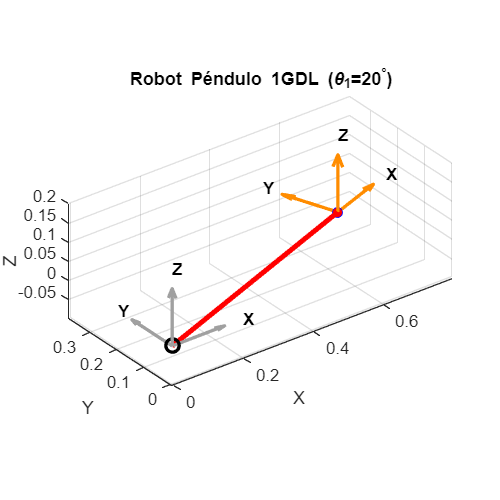


figure('Name', 'Robot Péndulo', 'Position', [1135-800, 350, 400, 400]);
plot3(0, 0, 0, 'ko', 'MarkerSize', 8, 'LineWidth', 2); hold on;
plot3(Pf_1GDL_num(1), Pf_1GDL_num(2), Pf_1GDL_num(3), 'bo', 'MarkerFaceColor', 'r');
plot3([0, Pf_1GDL_num(1)], [0, Pf_1GDL_num(2)], [0, Pf_1GDL_num(3)], 'r', 'LineWidth', 3);

grid on; axis equal; zlim([-0.1, 0.2]);

% Dibujar Ejes
q_base_1 = drawFrame(eye(4), s_scale); q_base_1.Color = '#A0A0A0'; 
q_pf_1 = drawFrame(H1_0_num, s_scale); q_pf_1.Color = '#FF8C00'; 

xlabel('X'); ylabel('Y'); zlabel('Z');
title(['Robot Péndulo 1GDL (\theta_1=' num2str(rad2deg(num_theta1)) '^\circ)']);
view(3);


% ============================================================
%  EVALUACIÓN Y GRÁFICA: ROBOT 2GDL (HOME EN X)
% ============================================================
Sigma1_X   = [H1_0_num(1,4); H1_0_num(2,4); H1_0_num(3,4)]; % Usamos la de 1GDL
H2_0_X_num = double(subs(H2_0_X_sym, sym_vars, num_vals));
Pf_X_num   = [H2_0_X_num(1,4); H2_0_X_num(2,4); H2_0_X_num(3,4)];

disp("--- Valores Numéricos HOME X (2 GDL) ---")

--- Valores Numéricos HOME X (2 GDL) ---


disp("Sigma 1 (Posición del Codo en X, Y, Z):"); disp(Sigma1_X');

Sigma 1 (Posición del Codo en X, Y, Z):
    0.6578    0.2394    0.0100



disp("Matriz H2_0_X (Posición y Orientación Final):"); disp(H2_0_X_num);

Matriz H2_0_X (Posición y Orientación Final):
    0.1736   -0.9848         0    0.7446
    0.9848    0.1736         0    0.7318
         0         0    1.0000    0.0200
         0         0         0    1.0000



disp("Punto Final Pf (X, Y, Z):"); disp(Pf_X_num');

Punto Final Pf (X, Y, Z):
    0.7446    0.7318    0.0200



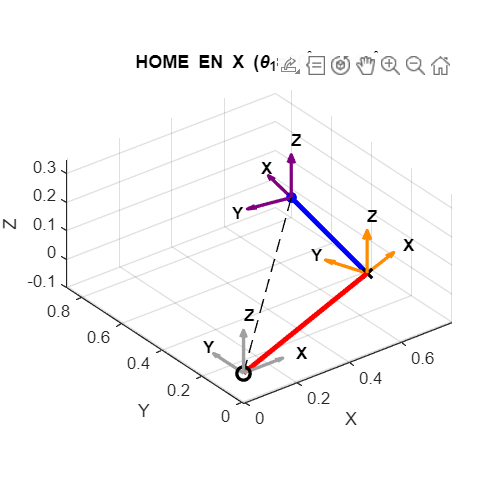


figure('Name', 'Robot 2GDL - Home en X', 'Position', [1135-400, 350, 400, 400]);
plot3(0, 0, 0, 'ko', 'MarkerSize', 8, 'LineWidth', 2); hold on;
plot3(Sigma1_X(1), Sigma1_X(2), Sigma1_X(3), 'kx', 'MarkerSize', 8, 'LineWidth', 2);
plot3(Pf_X_num(1), Pf_X_num(2), Pf_X_num(3), 'bo', 'MarkerFaceColor', 'b');
plot3([0, Sigma1_X(1)], [0, Sigma1_X(2)], [0, Sigma1_X(3)], 'r', 'LineWidth', 3);
plot3([Sigma1_X(1), Pf_X_num(1)], [Sigma1_X(2), Pf_X_num(2)], [Sigma1_X(3), Pf_X_num(3)], 'b', 'LineWidth', 3);
plot3([0, Pf_X_num(1)], [0, Pf_X_num(2)], [0, Pf_X_num(3)], 'k--');

grid on; axis equal; zlim([-0.1, 0.35]);

% Dibujar Ejes
q_base_x = drawFrame(eye(4), s_scale); q_base_x.Color = '#A0A0A0'; 
q_s1_x = drawFrame(H1_0_num, s_scale); q_s1_x.Color = '#FF8C00'; 
q_pf_x = drawFrame(H2_0_X_num, s_scale); q_pf_x.Color = '#800080'; 

xlabel('X'); ylabel('Y'); zlabel('Z');
title(['HOME EN X (\theta_1=' num2str(rad2deg(num_theta1)) '^\circ, \theta_2=' num2str(rad2deg(num_theta2)) '^\circ)']);
view(3);


% ============================================================
%  EVALUACIÓN Y GRÁFICA: ROBOT 2GDL (HOME EN Y)
% ============================================================
H1_0_Y_num = double(subs(H1_0_Y_sym, sym_vars, num_vals));
Sigma1_Y   = [H1_0_Y_num(1,4); H1_0_Y_num(2,4); H1_0_Y_num(3,4)];
H2_0_Y_num = double(subs(H2_0_Y_sym, sym_vars, num_vals));
Pf_Y_num   = [H2_0_Y_num(1,4); H2_0_Y_num(2,4); H2_0_Y_num(3,4)];

disp("--- Valores Numéricos HOME Y (2 GDL) ---")

--- Valores Numéricos HOME Y (2 GDL) ---


disp("Sigma 1 (Posición del Codo en X, Y, Z):"); disp(Sigma1_Y');

Sigma 1 (Posición del Codo en X, Y, Z):
   -0.2394    0.6578    0.0100



disp("Matriz H2_0_Y (Posición y Orientación Final):"); disp(H2_0_Y_num);

Matriz H2_0_Y (Posición y Orientación Final):
   -0.9848   -0.1736         0   -0.7318
    0.1736   -0.9848         0    0.7446
         0         0    1.0000    0.0200
         0         0         0    1.0000



disp("Punto Final Pf (X, Y, Z):"); disp(Pf_Y_num');

Punto Final Pf (X, Y, Z):
   -0.7318    0.7446    0.0200



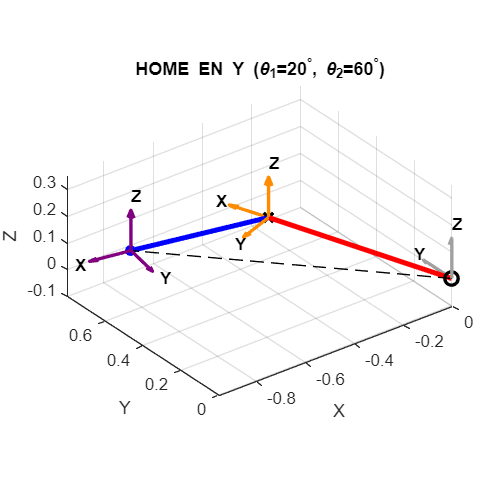


figure('Name', 'Robot 2GDL - Home en Y', 'Position', [1135, 350, 400, 400]);
plot3(0, 0, 0, 'ko', 'MarkerSize', 8, 'LineWidth', 2); hold on;
plot3(Sigma1_Y(1), Sigma1_Y(2), Sigma1_Y(3), 'kx', 'MarkerSize', 8, 'LineWidth', 2);
plot3(Pf_Y_num(1), Pf_Y_num(2), Pf_Y_num(3), 'bo', 'MarkerFaceColor', 'b');
plot3([0, Sigma1_Y(1)], [0, Sigma1_Y(2)], [0, Sigma1_Y(3)], 'r', 'LineWidth', 3);
plot3([Sigma1_Y(1), Pf_Y_num(1)], [Sigma1_Y(2), Pf_Y_num(2)], [Sigma1_Y(3), Pf_Y_num(3)], 'b', 'LineWidth', 3);
plot3([0, Pf_Y_num(1)], [0, Pf_Y_num(2)], [0, Pf_Y_num(3)], 'k--');

grid on; axis equal; zlim([-0.1, 0.35]); xlim([-0.95, 0]);

% Dibujar Ejes
q_base_y = drawFrame(eye(4), s_scale); q_base_y.Color = '#A0A0A0'; 
q_s1_y = drawFrame(H1_0_Y_num, s_scale); q_s1_y.Color = '#FF8C00'; 
q_pf_y = drawFrame(H2_0_Y_num, s_scale); q_pf_y.Color = '#800080'; 

xlabel('X'); ylabel('Y'); zlabel('Z');
title(['HOME EN Y (\theta_1=' num2str(rad2deg(num_theta1)) '^\circ, \theta_2=' num2str(rad2deg(num_theta2)) '^\circ)']);
view(3);



%% ==========================================================
%  BLOQUE 3: COMPROBACIÓN CINEMÁTICA INVERSA
%  ==========================================================
disp(" ")

disp("=== CINEMÁTICA INVERSA ===")

=== CINEMÁTICA INVERSA ===


% Comprobación Home en X
[q1_X, q2_X] = cinv_r2gdl(num_l1, num_l2, Pf_X_num(1), Pf_X_num(2));
disp("Ángulos calculados para Home X (Deberían ser 20 y 60):");

Ángulos calculados para Home X (Deberían ser 20 y 60):


disp(['q1 = ', num2str(q1_X), '° | q2 = ', num2str(q2_X), '°']);

q1 = 20° | q2 = 60°



% Comprobación Home en Y
[q1_Y, q2_Y] = cinv_r2gdl(num_l1, num_l2, Pf_Y_num(2), -Pf_Y_num(1));
disp("Ángulos calculados para Home Y (Deberían ser 20 y 60):");

Ángulos calculados para Home Y (Deberían ser 20 y 60):


disp(['q1 = ', num2str(q1_Y), '° | q2 = ', num2str(q2_Y), '°']);

q1 = 20° | q2 = 60°
